%updated code 
clc;
clear; 
cvx_clear;

%mu - gravitational parameter (m3/s2)
mu = 3.986e14

mu = 3.9860e+14


%radius of Earth (m)
r_e = 6.371e6

r_e = 6371000


%altitude of the target orbit (m)
%altitude = 422137

%a - radius of the target body's circular orbit (m)
%a = r_e + altitude

%sma from ppt
a = 6.85635e6

a = 6856350


%constant mean motion of target n = sqrt(mu/a^3)
%units: rad/s
n = sqrt(mu/a^3)

n = 0.0011


%number of states
nx = 6

nx = 6


%number of control inputs
nu = 3

nu = 3


%number of knot points
%this is to plan 2 minitues worth of controls
N = 121

N = 121


%timestep (seconds)
%need to wait at least 60 seconds between 
%successive thruster actuations. Encoded with 
%this timestep
dt = 1

dt = 1


%time history
thist = linspace(1, N*dt, N)

thist =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



%Target Spacecraft State
x0_target = zeros(1, nx)'

x0_target =      0
     0
     0
     0
     0
     0



%Chaser Spacecraft Initial State
%position - m
%velocity - m/s

%arbitrary state
%x0_chaser = [15.0, 20.0, 15.0, 10.0, 10.0, 0.0]'

%using the true data from the ppt
x0_chaser = [-0.2906951578333974,
             -258.73424997857484,
             1984.0093925290266,
             -2.2132577166418366,
             4.1627960172263556e-5,
             -0.00031920885703584645]

x0_chaser = 1.0e+03 *

   -0.0003
   -0.2587
    1.9840
   -0.0022
    0.0000
   -0.0000



%Clohessy Wiltshire Equations in statespace form

A = zeros(nx, nx)

A =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


A(1:3, 4:6) = eye(3)

A =      0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


A(4, 1) = 3*n^2

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


A(6, 3) = -n^2

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0         0         0
         0         0         0         0         0         0
         0         0   -0.0000         0         0         0


A(4, 5) = 2*n

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0    0.0022         0
         0         0         0         0         0         0
         0         0   -0.0000         0         0         0


A(5, 4) = -2*n

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    0.0000         0         0         0    0.0022         0
         0         0         0   -0.0022         0         0
         0         0   -0.0000         0         0         0



%mass of the satellite (kg) from data
m = 5.22

m = 5.2200


B = 1/m*[zeros(3,3); eye(3)]

B =          0         0         0
         0         0         0
         0         0         0
    0.1916         0         0
         0    0.1916         0
         0         0    0.1916



%Spacecraft Linear Dynamics
%CW equations
function xdot = spacecraft_dynamics(x, u)

    xdot = A*x + B*u

end

%Discretize the dynamics model 
%with matrix exponential

H = expm(dt*[A B; zeros(nu, nx+nu)])

H =     1.0000         0         0    1.0000    0.0011         0    0.0958    0.0001         0
   -0.0000    1.0000         0   -0.0011    1.0000         0   -0.0001    0.0958         0
         0         0    1.0000         0         0    1.0000         0         0    0.0958
    0.0000         0         0    1.0000    0.0022         0    0.1916    0.0002         0
   -0.0000         0         0   -0.0022    1.0000         0   -0.0002    0.1916         0
         0         0   -0.0000         0         0    1.0000         0         0    0.1916
         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0    1.0000



%Discrete Dynamics Matrices
Ad  = H(1:nx, 1:nx)

Ad =     1.0000         0         0    1.0000    0.0011         0
   -0.0000    1.0000         0   -0.0011    1.0000         0
         0         0    1.0000         0         0    1.0000
    0.0000         0         0    1.0000    0.0022         0
   -0.0000         0         0   -0.0022    1.0000         0
         0         0   -0.0000         0         0    1.0000


Bd = H(1:nx, (nx+1):end)

Bd =     0.0958    0.0001         0
   -0.0001    0.0958         0
         0         0    0.0958
    0.1916    0.0002         0
   -0.0002    0.1916         0
         0         0    0.1916



%initial position in target center
%coordinate frame
x_initial = x0_chaser

x_initial = 1.0e+03 *

   -0.0003
   -0.2587
    1.9840
   -0.0022
    0.0000
   -0.0000



%Goal is the target position
x_goal = x0_target

x_goal =      0
     0
     0
     0
     0
     0



cvx_begin


   %solver 
   cvx_solver sedumi

   %precision for solver tolerance
   cvx_precision('low')

   %maximum iterations
   %cvx_solver_settings('maxit', 1000);

    %state trajectory 
   variable X(nx, N)

   %Controls
   variable U(nu, N-1)

   %minimize the L1 norm to get bang bang controls
   minimize(norm(U(:),1) + norm(X(:), 2))

   subject to

       %initial state
       X(:,1) == x_initial
    
       %Goal constraint
       %X(:, N) == x_goal
    
       %Thrust Limit Constraint
       %currently infeasible. removing this 
       %it solves when removing this constraint and 
       %we get impulsive controls
       for k=1:(N-1)
           %maximum 4.6 mm/s for 1 second burn
           norm(U(:,k), 1) <= 4.6e-3

       end
    
       %Dynamics Constraints
    
       for k=1:N-1
           X(:,k+1) == Ad*X(:,k) + Bd*U(:,k)
       end

       %successive controls must be 60 seconds apart
       for k = 2:60
            U(:, k) == zeros(3,1)
       end

       for k = 62:N-1
            U(:, k) == zeros(3,1)
       end
       
cvx_end

 
Calling SeDuMi 1.02,: 2287 variables, 1560 equality constraints
------------------------------------------------------------
SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
eqs m = 1560, order n = 1563, dim = 2288, blocks = 2
nnz(A) = 8154 + 0, nnz(ADA) = 13508, nnz(L) = 10280
Handling 1 + 1 dense columns.
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.32E+05 0.000
  1 :   1.86E+04 2.87E+05 0.000 0.8631 0.9000 0.9000   2.62  1  1  1.3E+01
  2 :   5.90E+03 6.07E+04 0.000 0.2115 0.9000 0.9000   2.54  1  1  2.2E+00
  3 :   8.70E+03 2.06E+04 0.000 0.3388 0.9000 0.9000   1.18  1  1  9.7E-01
  4 :   1.02E+04 1.22E+04 0.000 0.5957 0.9000 0.9000   1.00  1  1  7.2E-01
  5 :   1.27E+04 8.36E+03 0.000 0.6829 0.9000 0.9000   0.75  1  1  6.1E-01
  6 :   1.41E+04 6.51E+03 0.000 0.7784 0.9000 0.9000   0.52  1  1  5.5E-01
  7 :   1.58E+04 4.56E+03 0.000 0.7005 

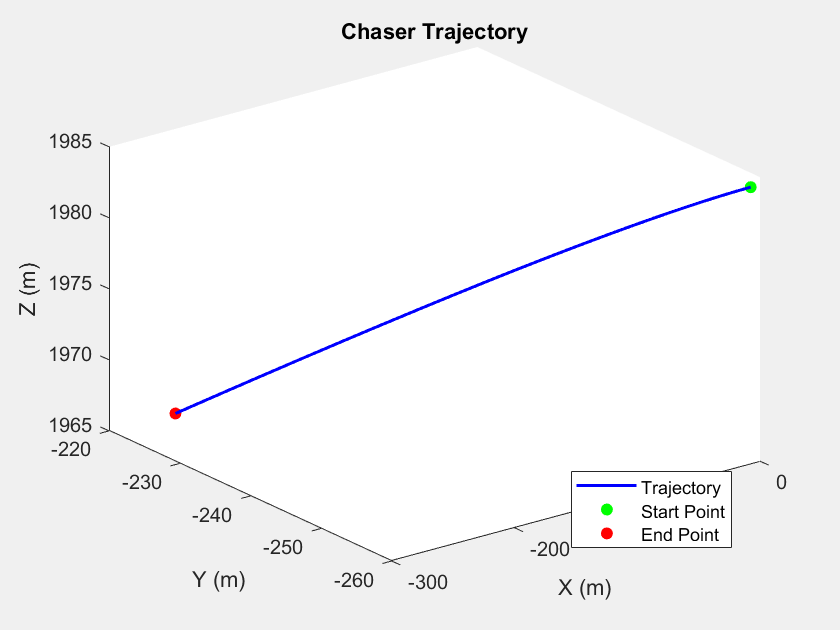







figure('Name', 'My Plot', 'NumberTitle', 'off', 'Visible', 'on');

% Plot the data
plot3(X(1,:), X(2,:), X(3,:), '-b', 'LineWidth', 1.5);
hold on
scatter3(X(1,1), X(2,1), X(3,1), "green", "filled")
scatter3(X(1,N), X(2,N), X(3,N), "red", "filled")
hold off

% Add title and labels
title('Chaser Trajectory');
xlabel('X (m)');
ylabel('Y (m)');
zlabel("Z (m)")

legend('Trajectory', 'Start Point', 'End Point', 'Location', 'best');

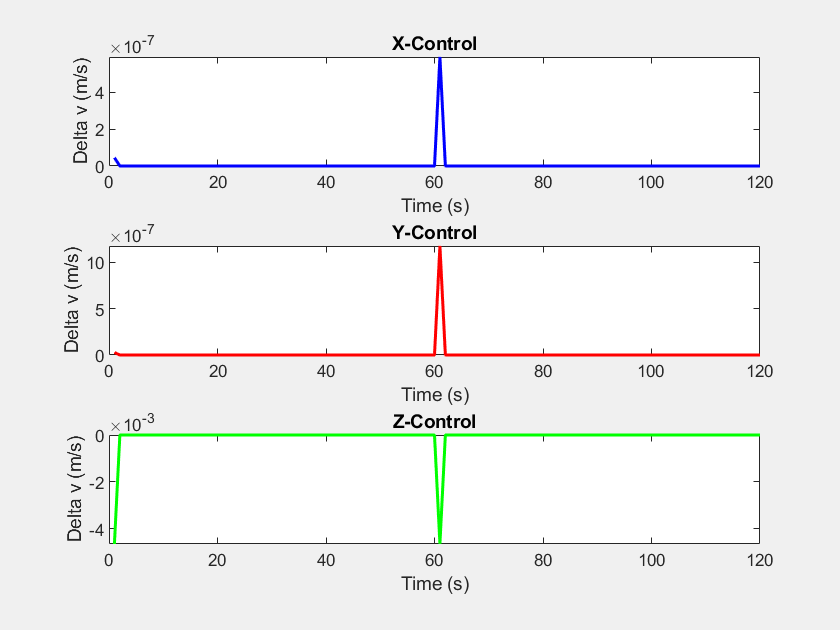


% Create a new figure window
figure('Name', 'Multiple Subplots', 'NumberTitle', 'off', 'Visible', 'on', 'WindowStyle', 'normal');

% First subplot
subplot(3, 1, 1); 
plot(thist(1, 1:N-1), U(1,:), '-b', 'LineWidth', 1.5); 
title('X-Control');
xlabel('Time (s)');
ylabel('Delta v (m/s)');

% Second subplot
subplot(3, 1, 2);
plot(thist(1, 1:N-1), U(2,:), '-r', 'LineWidth', 1.5); 
title('Y-Control');
xlabel('Time (s)');
ylabel('Delta v (m/s)');

% Third subplot
subplot(3, 1, 3); 
plot(thist(1, 1:N-1), U(3,:), '-g', 'LineWidth', 1.5); 
title('Z-Control');
xlabel('Time (s)');
ylabel('Delta v (m/s)');